Cell = readcell('Datasets\Task2\LetterClassification_GT.xlsx');

% Extract 
letters = Cell(4:41, 3);  
img_name = Cell(4:41, 2);

letters_array = cellfun(@char, letters, 'UniformOutput', false);
img_array = cellfun(@char, img_name, 'UniformOutput', false);

% Convert the cell array to a character array
%letter_string = cell2mat(letters);
%img_string= cell2mat(img_name);
% Initialize empty vectors for each group
vectorA = {};
vectorB = {};
vectorC = {};
vectorI = {};
vectorL = {};
vectorV = {};
vectorW = {};

% Iterate through each element of letters
for i = 1:length(letters_array)
    
    % Check the letter and group accordingly
    if isequal(letters_array(i), "A");
        vectorA{end+1} = img_array{i};
    elseif isequal(letters_array(i), "B");
       vectorB{end+1} = img_array{i};
    elseif isequal(letters_array{i}, "C")
        vectorC{end+1} = img_array{i};
    elseif isequal(letters_array{i}, "I")
        vectorI{end+1} = img_array{i};
    elseif isequal(letters_array{i}, 'L')
        vectorL{end+1} = img_array{i};
    elseif isequal(letters_array{i}, 'V')
        vectorV{end+1} = img_array{i};
    elseif isequal(letters_array{i}, 'W')
        vectorW{end+1} = img_array{i};
    end
end

% Expressão regular para extrair os números
expressao_regular = '(\d+)';

% Loop para extrair os números de cada string
for i = 1:length(vectorA)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorA{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecA{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorB)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorB{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecB{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorC)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorC{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecC{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorI)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorI{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecI{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorL)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorL{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecL{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorV)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorV{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecV{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorW)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorW{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecW{i} = str2double(numeros_encontrados{1}{1});
end


% Directory path
directory = 'Datasets\Task2\Images_with_BBs';

%%%%%%%%fazer isto para a imagem 1 chamada image com texto .name no inicio%%%%%%%%
% Get a list of all files in the directory
fileList = dir(fullfile(directory, '*.tif'));

% Loop through the list and read each image
images = cell(1, numel(fileList)); % Initialize cell array to store images

for i =1:numel(fileList)
    % Get the file name
    fileName = fullfile(directory, fileList(i).name);
    
    % Read the image
    image = imread(fileName);
    % Convert the image to grayscale
    grayImage = rgb2gray(image);
    
    % Create a bounding box around the coloured region eliminating the black background
    % Find the bounding box of the coloured region
    [rows, columns, ~] = find(grayImage ~= 0);
    % Get the bounding box
    boundingBox = [min(columns), min(rows), max(columns) - min(columns), max(rows) - min(rows)];

    % Crop the image using the bounding box
    croppedImage = imcrop(image, boundingBox);

    % Resize image to 64 x 64
    resizedImage = imresize(croppedImage, [64, 64]);

    % Convert the image to grayscale
    graycroppedImage = rgb2gray(resizedImage);

    %% ver o contorno da imagem - copiar da task1 ou do exemplo do help jaccard

    %% Binarize
   %% binaryImage = imbinarize(graycroppedImage, 0.5);
    %%binaryTemplate = imbinarize(resizedtemplateA, 0.5);

     % Use active contours to segment the hand. (temporario)
      mask = false(size(graycroppedImage));
      mask(5:end-5,5:end-5) = true;
      img = activecontour(graycroppedImage, mask, 250);
      images{i} = img;
end

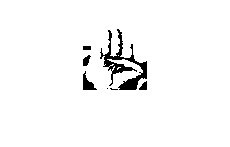


imshow(images{i});

for i = 1:length(images)
total = [0, 0, 0, 0, 0, 0, 0];
correlation = [0, 0, 0, 0, 0, 0, 0];
disp(i);
for j = 1:length(vecA)
    indice = vecA(j);
    if ~(i == indice{1})
            correlationA = normxcorr2(images{i}, images{indice{1}});
              [maxCorrA, maxIndexA] = max(abs(correlationA(:)));
            correlation(1) =  correlation(1) + maxCorrA;  %% acumula
            total(1) = total(1) + 1;  % n da para contar pelo length do vetor porque a imagem pode estar naquele conjunto

    end
end
% Calcula a média da correlação
correlation(1) = correlation(1) / total(1);
disp(correlation(1));

for j = 1:length(vecB)
    indice = vecB(j);
    if ~(i == indice{1})
            correlationB = normxcorr2(images{i}, images{indice{1}});
              [maxCorrB, maxIndexB] = max(abs(correlationB(:)));
            correlation(2) =  correlation(2) + maxCorrB;
            total(2) = total(2) + 1; 

    end
end
% Calcula a média da correlação
correlation(2) = correlation(2) / total(2);
disp(correlation(2));

for j = 1:length(vecC)
    indice = vecC(j);
    if ~(i == indice{1})
            correlationC = normxcorr2(images{i}, images{indice{1}});
              [maxCorrC, maxIndexC] = max(abs(correlationC(:)));
            correlation(3) =  correlation(3) + maxCorrC;
            total(3) = total(3) + 1;

    end
end
% Calcula a média da correlação
correlation(3) = correlation(3) / total(3);
disp(correlation(3));

for j = 1:length(vecI)
    indice = vecI(j);
    if ~(i == indice{1})
            correlationI = normxcorr2(images{i}, images{indice{1}});
              [maxCorrI, maxIndexI] = max(abs(correlationI(:)));
            correlation(4) =  correlation(4) + maxCorrI;
            total(4) = total(4) + 1;  

    end
end
% Calcula a média da correlação
correlation(4) = correlation(4) / total(4);
disp(correlation(4));

for j = 1:length(vecL)
    indice = vecL(j);
    if ~(i == indice{1})
            correlationL = normxcorr2(images{i}, images{indice{1}});
              [maxCorrL, maxIndexL] = max(abs(correlationL(:)));
            correlation(5) =  correlation(5) + maxCorrL;
            total(5) = total(5) + 1;  

    end
end
% Calcula a média da correlação
correlation(5) = correlation(5) / total(5);
disp(correlation(5));

for j = 1:length(vecV)
    indice = vecV(j);
    if ~(i == indice{1})
            correlationV = normxcorr2(images{i}, images{indice{1}});
              [maxCorrV, maxIndexV] = max(abs(correlationV(:)));
            correlation(6) =  correlation(6) + maxCorrV;
            total(6) = total(6) + 1;  

    end
end
% Calcula a média da correlação
correlation(6) = correlation(6) / total(6);
disp(correlation(6));

for j = 1:length(vecW)
    indice = vecW(j);
    if ~(i == indice{1})
            correlationW = normxcorr2(images{i}, images{indice{1}});
              [maxCorrW, maxIndexW] = max(abs(correlationW(:)));
            correlation(7) =  correlation(7) + maxCorrW;
            total(7) = total(7) + 1;  

    end
end
% Calcula a média da correlação
correlation(7) = correlation(7) / total(7);
disp(correlation(7));

[maxValue, maxPosition] = max(correlation);
if maxPosition == 1
    result{i} = 'A';
elseif maxPosition == 2
    result{i} = 'B';
elseif maxPosition == 3
    result{i} = 'C';
elseif maxPosition == 4
    result{i} = 'I';
elseif maxPosition == 5
    result{i} = 'L';
elseif maxPosition == 6
    result{i} = 'V';
elseif maxPosition == 7
    result{i} = 'W';
end
disp(result{i});
end

     1



    0.5299



    0.5439



    0.4484



    0.4764



    0.4858



    0.5192



    0.5253



B


     2



    0.5655



    0.5838



    0.5280



    0.5658



    0.6301



    0.5436



    0.5622



L


     3



    0.4364



    0.4515



    0.4103



    0.4152



    0.4093



    0.4252



    0.4623



W


     4



    0.4637



    0.4636



    0.5081



    0.4427



    0.4457



    0.4858



    0.4743



C


     5



    0.3313



    0.3558



    0.3145



    0.3167



    0.2886



    0.3239



    0.3361



B


     6



    0.4633



    0.4666



    0.4575



    0.4444



    0.4271



    0.4208



    0.4448



B


     7



    0.5707



    0.5179



    0.4834



    0.4564



    0.4467



    0.5069



    0.5447



A


     8



    0.5233



    0.5032



    0.4536



    0.4766



    0.4651



    0.5551



    0.5185



V


     9



    0.5157



    0.5137



    0.4449



    0.4736



    0.5115



    0.5360



    0.6008



W


    10



    0.4506



    0.4705



    0.4696



    0.4535



    0.4562



    0.5207



    0.5858



W


    11



    0.4169



    0.4624



    0.4575



    0.4091



    0.4191



    0.4206



    0.4506



B


    12



    0.4732



    0.4485



    0.4574



    0.4684



    0.4655



    0.5031



    0.4937



V


    13



    0.5244



    0.4641



    0.4476



    0.4108



    0.4649



    0.4184



    0.4064



A


    14



    0.4976



    0.4853



    0.5128



    0.4276



    0.4567



    0.4600



    0.4665



C


    15



    0.5643



    0.5321



    0.4949



    0.4946



    0.4626



    0.5037



    0.5231



A


    16



    0.5904



    0.5461



    0.5639



    0.5644



    0.5751



    0.5822



    0.5822



A


    17



    0.5834



    0.5831



    0.5394



    0.5559



    0.6350



    0.5637



    0.5929



L


    18



    0.4387



    0.4502



    0.4120



    0.4092



    0.3736



    0.4441



    0.4184



B


    19



    0.4426



    0.4454



    0.5470



    0.4377



    0.4885



    0.4938



    0.4902



C


    20



    0.4139



    0.4299



    0.4012



    0.3182



    0.3581



    0.3975



    0.3813



B


    21



    0.5313



    0.5308



    0.4923



    0.4714



    0.4997



    0.4953



    0.4844



A


    22



    0.6206



    0.5845



    0.6271



    0.5457



    0.6020



    0.6523



    0.5913



V


    23



    0.6260



    0.5554



    0.5779



    0.4870



    0.4781



    0.5492



    0.5435



A


    24



    0.5089



    0.4780



    0.4870



    0.4867



    0.5560



    0.5276



    0.5386



L


    25



    0.4473



    0.4316



    0.5291



    0.4289



    0.4720



    0.4805



    0.4527



C


    26



    0.6864



    0.6972



    0.6528



    0.5958



    0.5779



    0.6559



    0.6379



B


    27



    0.4738



    0.4819



    0.4768



    0.4652



    0.4294



    0.5501



    0.5284



V


    28



    0.6105



    0.6385



    0.5711



    0.5632



    0.6673



    0.5640



    0.5749



L


    29



    0.5602



    0.5475



    0.4808



    0.4350



    0.4354



    0.5061



    0.5173



A


    30



    0.4744



    0.4878



    0.4828



    0.4532



    0.4641



    0.5239



    0.6054



W


    31



    0.4874



    0.5381



    0.5015



    0.5092



    0.5218



    0.5355



    0.5339



B


    32



    0.5101



    0.5188



    0.4675



    0.4996



    0.5572



    0.5398



    0.5659



W


    33



    0.4423



    0.4460



    0.4269



    0.3938



    0.4182



    0.4275



    0.4323



B


    34



    0.4133



    0.4073



    0.4078



    0.4164



    0.4066



    0.4220



    0.4272



W


    35



    0.6060



    0.6409



    0.5401



    0.5247



    0.5163



    0.5699



    0.5766



B


    36



    0.5166



    0.5169



    0.4587



    0.4888



    0.5401



    0.5524



    0.5765



W


    37



    0.4621



    0.4875



    0.4551



    0.4808



    0.4475



    0.5488



    0.5162



V


    38



    0.3360



    0.3364



    0.3252



    0.3272



    0.3093



    0.3551



    0.3362



V



    tasserto = 0;
for i= 1:length(result)
    if isequal(result{i}, letters_array{i})
        tasserto = tasserto + 1;
    else
        fprintf("ERRADO imagem n %d ...resultado obtido = %s ...resultado esperado = %s\n", i, result{i}, letters_array{i});
    end
end

ERRADO imagem n 3 ...resultado obtido = W ...resultado esperado = B
ERRADO imagem n 5 ...resultado obtido = B ...resultado esperado = W
ERRADO imagem n 6 ...resultado obtido = B ...resultado esperado = A
ERRADO imagem n 11 ...resultado obtido = B ...resultado esperado = I
ERRADO imagem n 12 ...resultado obtido = V ...resultado esperado = L
ERRADO imagem n 15 ...resultado obtido = A ...resultado esperado = B
ERRADO imagem n 18 ...resultado obtido = B ...resultado esperado = I
ERRADO imagem n 22 ...resultado obtido = V ...resultado esperado = B
ERRADO imagem n 23 ...resultado obtido = A ...resultado esperado = I
ERRADO imagem n 26 ...resultado obtido = B ...resultado esperado = I
ERRADO imagem n 29 ...resultado obtido = A ...resultado esperado = W
ERRADO imagem n 31 ...resultado obtido = B ...resultado esperado = I
ERRADO imagem n 32 ...resultado obtido = W ...resultado esperado = V
ERRADO imagem n 33 ...resultado obtido = B ...resultado esperado = V
ERRADO imagem n 34 ...resultado obtid

disp(tasserto);

    21



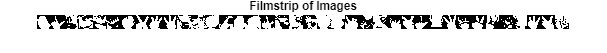



figure;
montage(images, 'Size', [1, numel(fileList)]); title('Filmstrip of Images');

% Compute the confusion matrix
confMat = confusionmat(letters_array, result);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


figure;
disp(confMat);

     2     0     0     1     1     2     0
     0     4     0     0     0     1     0
     0     0     4     0     0     0     0
     1     0     0     4     1     0     0
     1     0     0     0     4     0     0
     2     0     0     1     0     3     0
     4     0     0     1     1     0     0



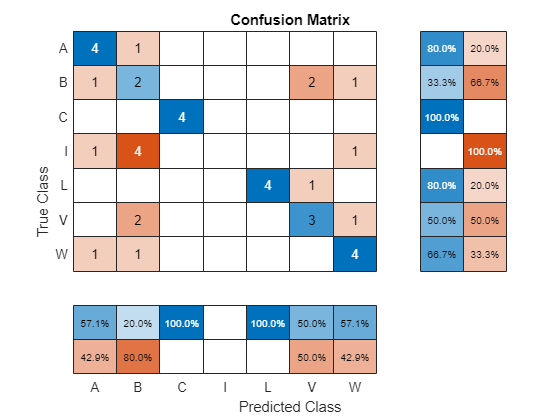


% Create a confusion chart
confChart = confusionchart(letters_array, result);

% Customize the confusion chart 
confChart.Title = 'Confusion Matrix';
confChart.RowSummary = 'row-normalized';
confChart.ColumnSummary = 'column-normalized';